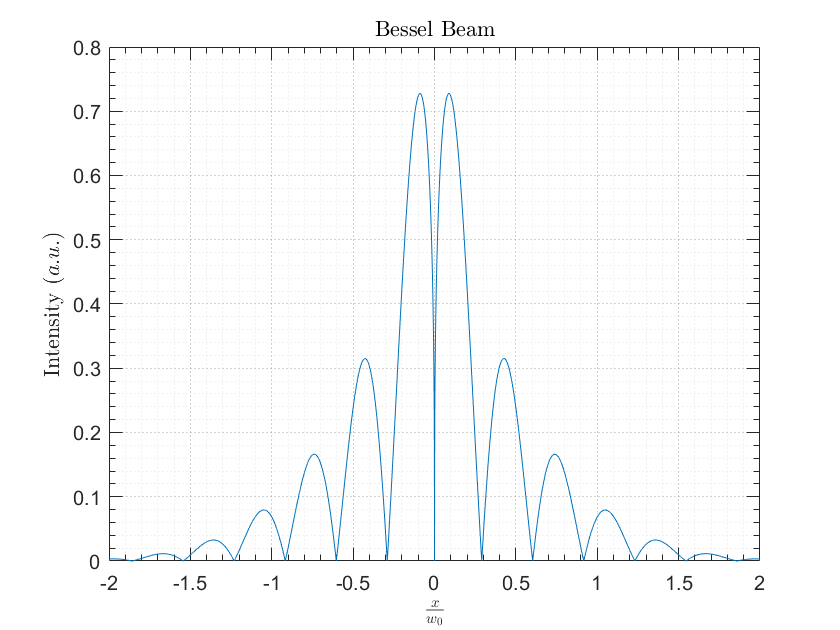

%******************* Bessel-gaussian beam *******************%

q = 0.333;                          % Bessel function order
w0 = 10;                        % Beam waist

L = -20:0.001:20;
J = abs(besselj(q,L));          % Bessel beam 1D envelope
G = exp(-(L.^2)/(w0.^2));       % Gaussian 1D envelope
A = J.*G;                       % Bessel-Gaussian beam

figure;
plot(L/w0,A)
title("Bessel Beam", "Interpreter","latex")
xlabel("$\frac{x}{w_0}$", "Interpreter","latex")
ylabel("Intensity $(a.u.)$", "Interpreter","latex")
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid

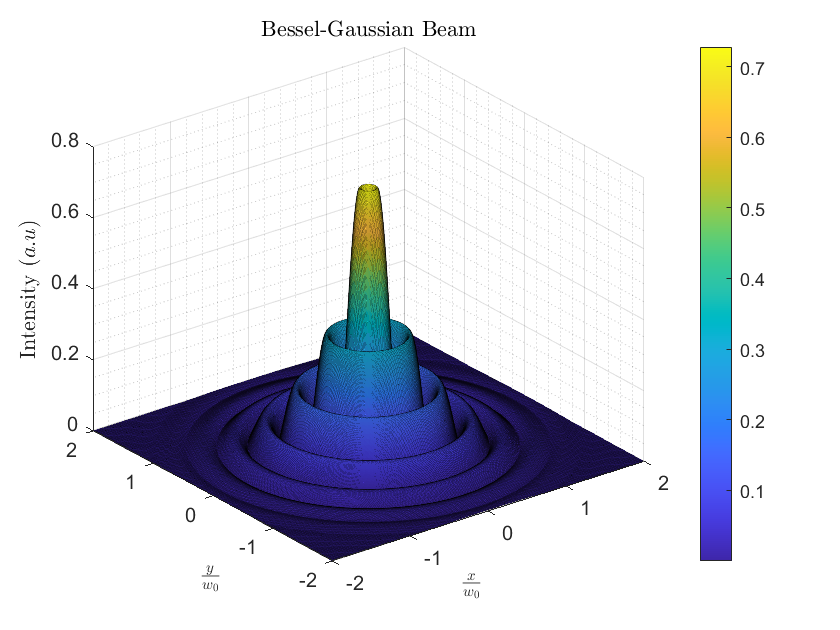


N = 500;
LR = linspace(-20,20,N);       
x = LR;
y = x';
r = sqrt(x.^2 + y.^2);
J = abs(besselj(q,r));          % Bessel beam spacial envelope
G = exp(-(r.^2)/(w0.^2));       % Gaussian spacial envelope
AR = J.*G;                       % Bessel-Gaussian beam

figure;
surf(x/w0,y/w0,AR, 'EdgeColor', [0, 0, 0], 'EdgeAlpha', 0.2)
title("Bessel-Gaussian Beam", "Interpreter","latex")
xlabel("$\frac{x}{w_0}$", "Interpreter","latex")
ylabel("$\frac{y}{w_0}$", "Interpreter","latex")
zlabel("Intensity $(a.u)$", "Interpreter","latex")
grid on
grid minor
colorbar
colormap parula